# Creating a Planar Non-Orthotropic Closure

The function `fitNonOrtho2D` will generate data and fit it with polynomials in order to create a non-orthotropic (F type) closure.  Here is an example.  (The process for fitting an orthotropic closure using `fitOrtho2D` is similar).

First, set up some parameters.  Let's say that you want to add a closure specifically for $C_I = 0.06$.  

CI    = 0.06; % Interaction coefficient
xi    = 1;    % Particle shape factor
n1    = 3;    % Polynomial order, eta_1
n2    = n1;   % Polynomial order, eta_2
% alpha values control flow types in fitting data
alpha = [-0.8, -0.15, 0, 0.15, 0.3, 0.5, 0.7, 1];
dt    = 0.1;  % Time step for fitting data
tend  = 15;   % Max time for fitting data
iplot = 1;    % Plot the data and fits

Now generate the fitting data and determine the polynomial coefficients for the fit.  Using `iplot = 1` causes `fitNonOrtho2D` to generate the plots shown here.

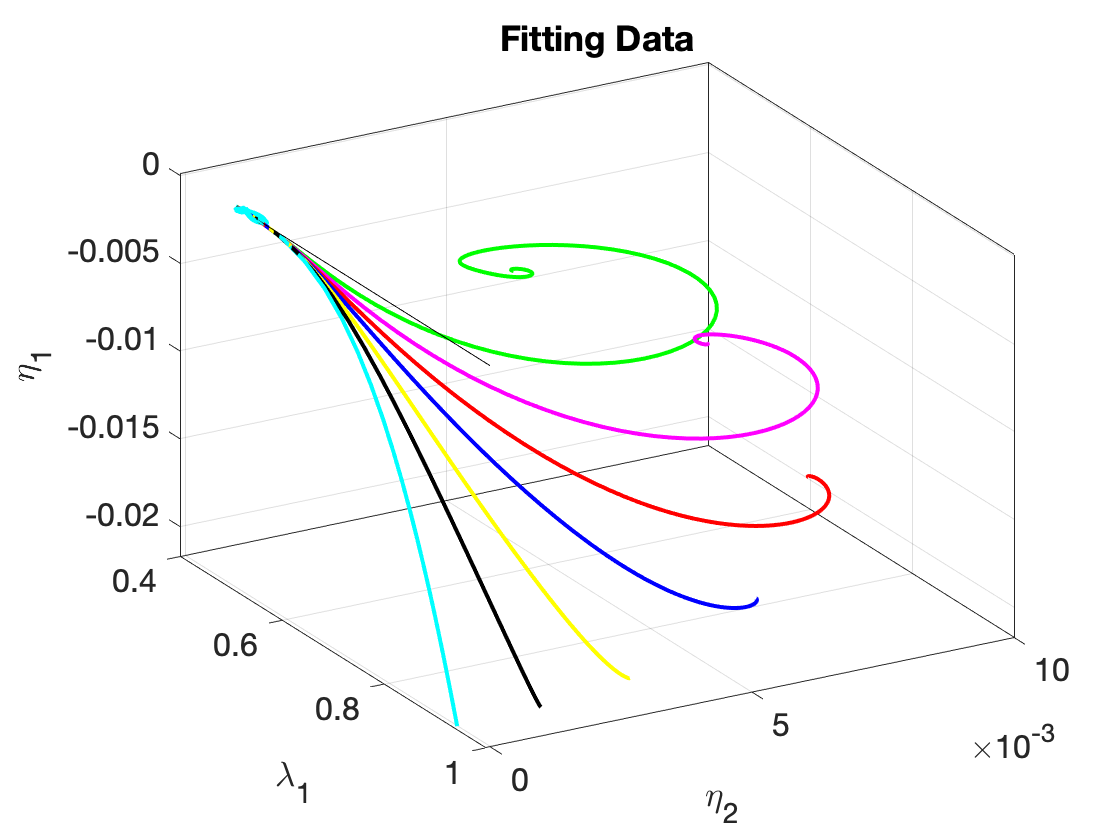

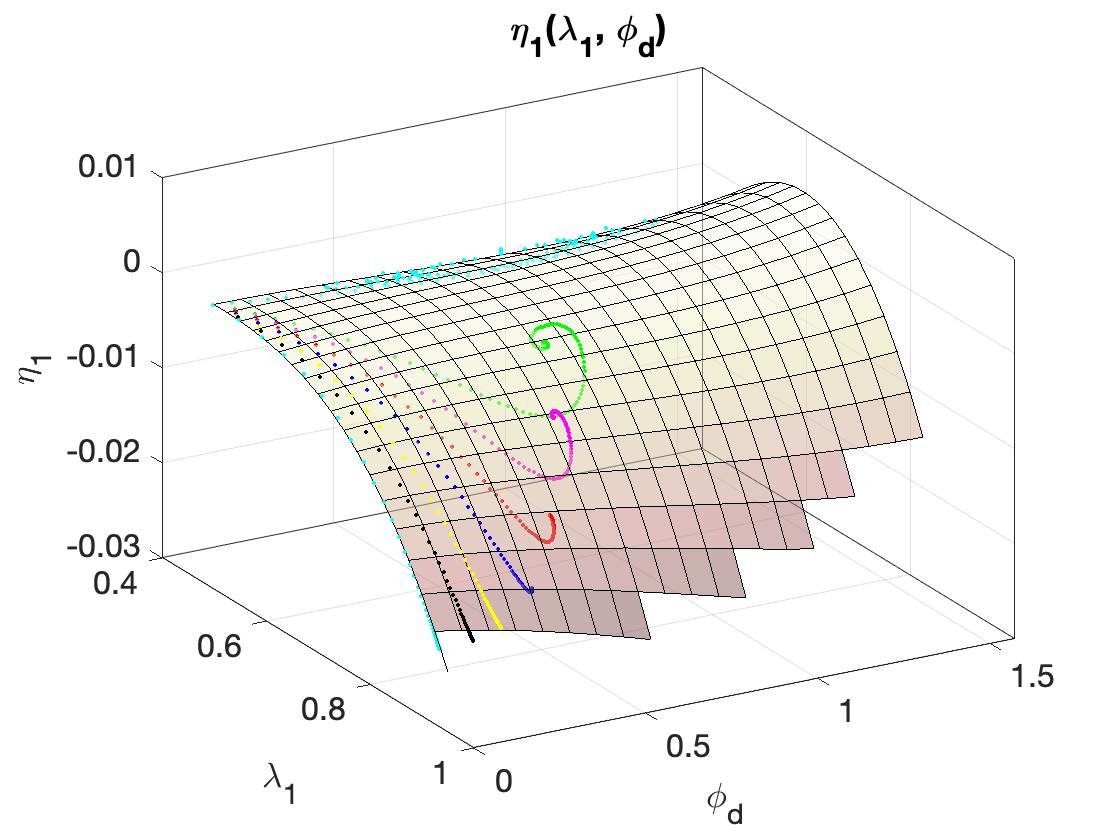

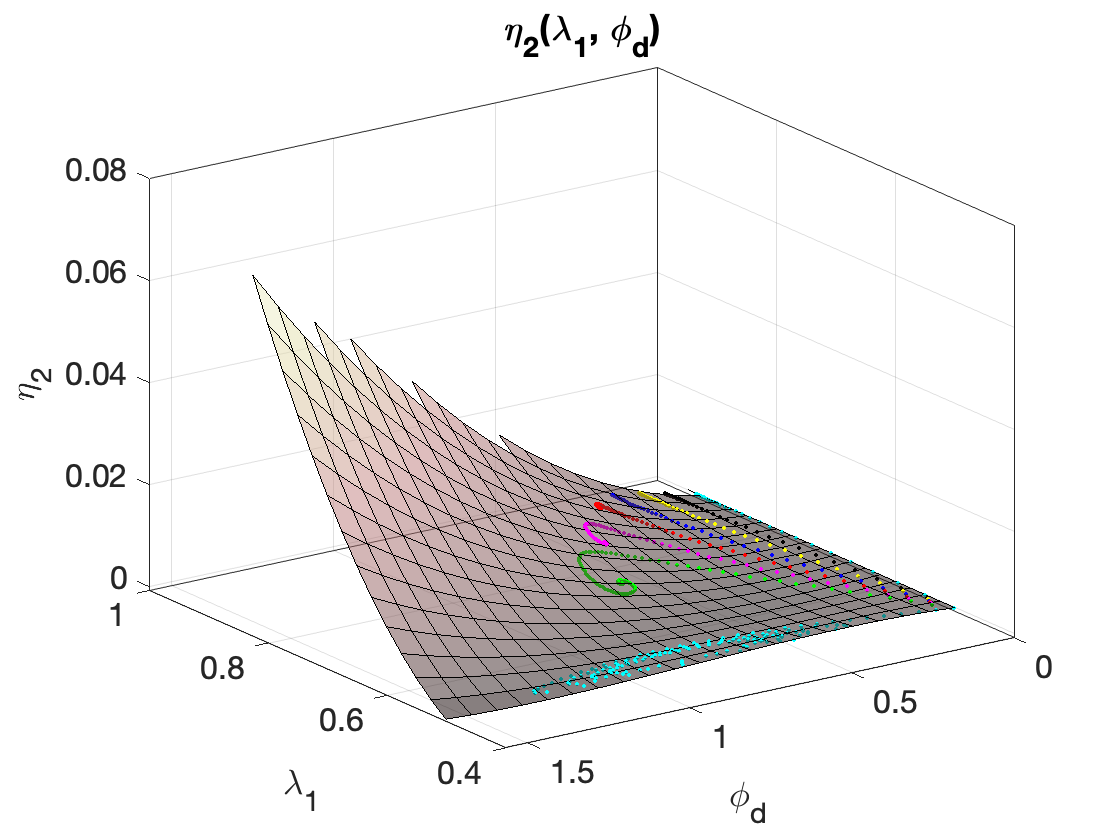

[a1, a2, err1, err2] = fitNonOrtho2D(CI, xi, ...
          n1, n2, alpha, dt, tend, iplot);

fprintf('RMS fitting errors:\n')

RMS fitting errors:


fprintf('   %8.2e for eta_1\n', err1)

   2.22e-04 for eta_1


fprintf('   %8.2e for eta_2\n', err2)

   2.29e-04 for eta_2


The polynomial coefficents are in the vectors `a1` and `a2`, in the form that can be used by `polyval2`.

To add this closure to `closeA4planar`, open that file in the Matlab editor, scroll to the section for the F closures, and add a new `case` for the $C_I$ value.  Use `printCoeff` to print the coefficients in `a1` to the console, copy them, and paste them into `closeA4planar.m`.  Repeat for the `a2` coefficients, save `closeA4planar.m`, and you are done.  Here's what the coefficients look like:

fprintf('\n\nCoefficients:\n')



Coefficients:


printCoeff(a1, 'a1', 3)

   a1 = [ 0.015057847375565, ...
         -0.107576883234515, ...
         -0.055898298134520, ...
          0.248876850740880, ...
          0.179271573400223, ...
          0.000481554685365, ...
         -0.187908947548217, ...
         -0.134926452970737, ...
         -0.007661654654218, ...
          0.002396980760498];


printCoeff(a2, 'a2', 3)

   a2 = [-0.000000000000000, ...
          0.000000000000001, ...
          0.107946710464152, ...
         -0.000000000000002, ...
         -0.329120295770948, ...
         -0.053920117202692, ...
          0.000000000000001, ...
          0.244123592541511, ...
          0.091221630856207, ...
          0.003428556175052];
